# Input basic information for file names

experimentNumber = 'test';
subject = '1(Li)';
excelDataFilePath = "D:\OneDrive\Desktop\Graduate Project\log\工作簿1.xlsx"

excelDataFilePath = "D:\OneDrive\Desktop\Graduate Project\log\工作簿1.xlsx"

PPGTitle="LED1\_PPG data from experiment" + experimentNumber + " for subject" +subject; 
accTitle="Accelerometer Data from experiment"+experimentNumber+" for subject"+subject;
finalTitle = "Accelerometer and PPG Data from experiment"+experimentNumber+" for subjet"+subject ;

exportPath = "./Subject" + subject + "/experiment" +experimentNumber;

if ~exist(exportPath,'dir')
    mkdir(exportPath)
end

# Read the Excel file

data = readtable(excelDataFilePath);

# Preprocessing data

%  Format timestamp into seconds
data.Timestamp = datetime(data.Timestamp_Day_Month_YearHour_Minute_Second_Milisecond_, 'InputFormat', 'dd.MM.yyyy HH:mm:ss:SSS');
data.Time_in_seconds = seconds(data.Timestamp - data.Timestamp(1));

% Smooth processing for the PPG and ACC data
smoothed_LED1 = smooth(data.LED1_PPG1, 0.01, 'rloess'); 
smoothed_LED2 = smooth(data.LED2_PPG1, 0.01, 'rloess'); 
smoothed_LED3 = smooth(data.LED3_PPG1, 0.01, 'rloess'); 

smoothed_acc_x = smooth(data.ACC_X_mg_, 0.01, 'rloess'); 
smoothed_acc_y = smooth(data.ACC_Y_mg_, 0.01, 'rloess'); 
smoothed_acc_z = smooth(data.ACC_Z_mg_, 0.01, 'rloess'); 



% Calculate the mean of two PPGs
% data.PPG_avg = mean([smoothed_LED1,smoothed_LED2],2);
disp(['Time range: ', num2str(min(data.Time_in_seconds)), ' to ', num2str(max(data.Time_in_seconds)), ' seconds']);

Time range: 0 to 33.74 seconds


# Plot PPG data

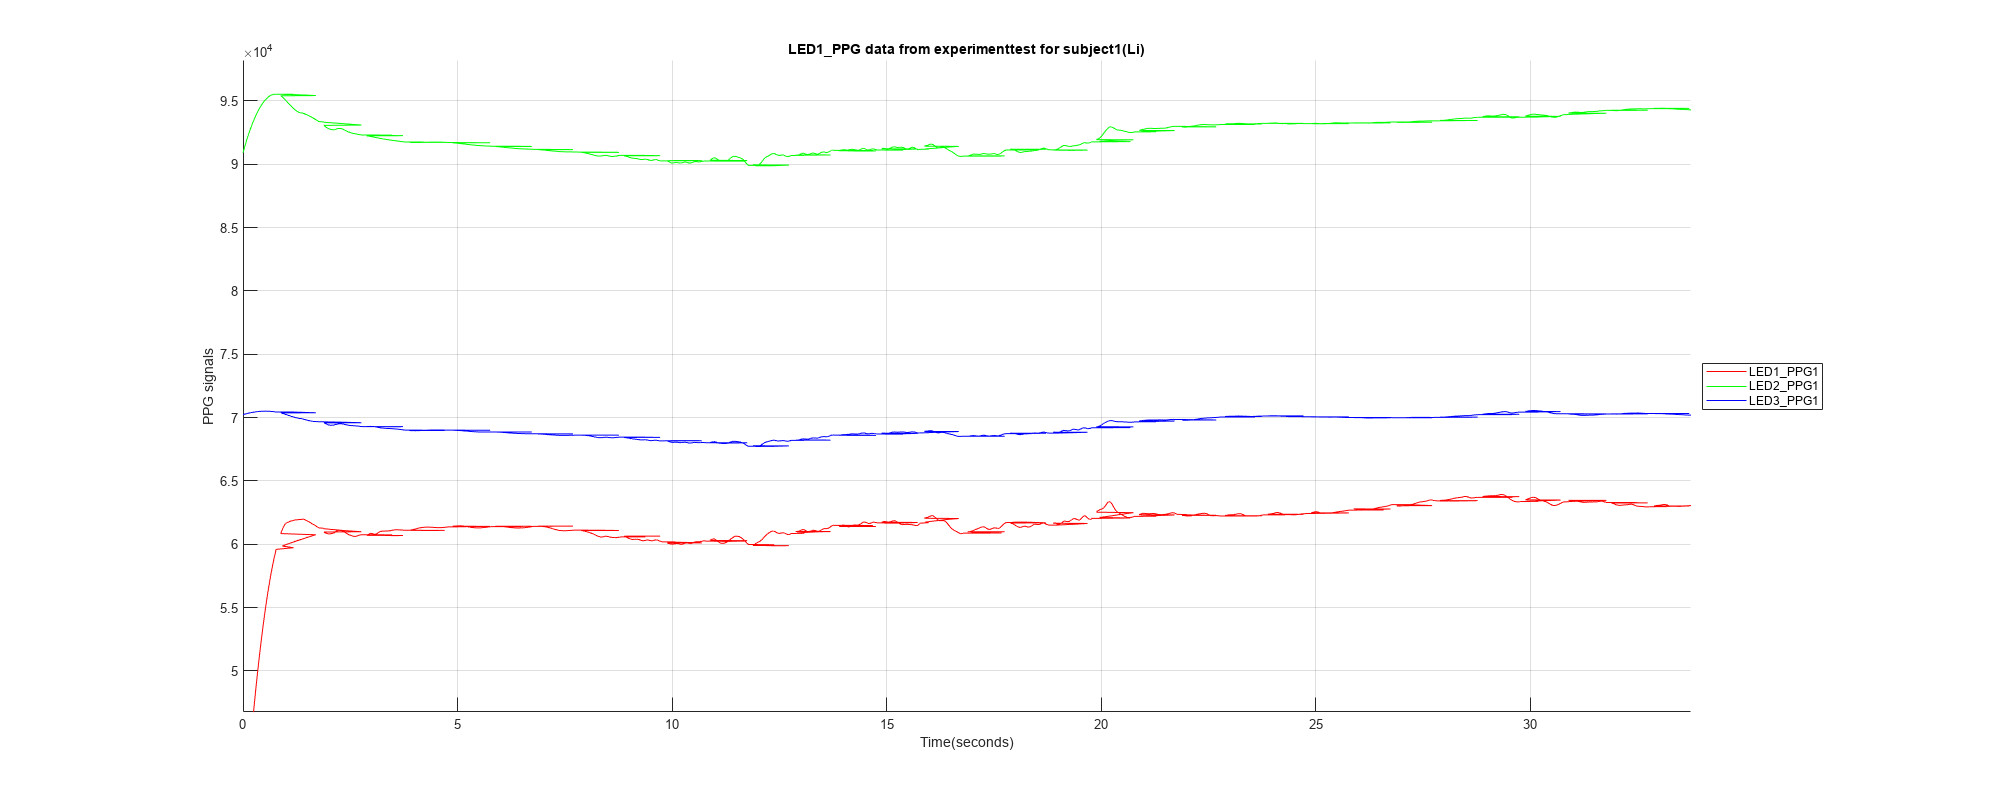

figure;
hold on;
set(gcf, 'Position', [100, 100, 2000, 800]);  % [x, y, width, height]

% plot(data.Time_in_seconds,data.PPG_avg,'g', 'DisplayName', 'LED1_PPG1_AVG');
plot(data.Time_in_seconds, smoothed_LED1, 'r', 'DisplayName', 'LED1\_PPG1');
plot(data.Time_in_seconds, smoothed_LED2, 'g', 'DisplayName', 'LED2\_PPG1');
plot(data.Time_in_seconds, smoothed_LED3, 'b', 'DisplayName', 'LED3\_PPG1');

xlabel('Time(seconds)');
ylabel('PPG signals');
title(PPGTitle);
grid on;
legend(Location="eastoutside");
hold off;

xlim([0 max(data.Time_in_seconds)]);


exportgraphics(gcf, exportPath+"\PPG data for experiment"+ experimentNumber +" of subject"+subject+".png", 'Resolution', 1000);

# Plot Accelerometer Data

% Plot accelerometer data
figure;
set(gcf, 'Position', [100, 100, 2000, 800]);  % [x, y, width, height]
hold on;
plot(data.Time_in_seconds, smoothed_acc_x, 'r', 'DisplayName', 'ACC_X');
plot(data.Time_in_seconds, smoothed_acc_y, 'g', 'DisplayName', 'ACC_Y');
plot(data.Time_in_seconds, smoothed_acc_z, 'b', 'DisplayName', 'ACC_Z');

xlabel('Time (seconds)');
ylabel('Acceleration (mg)');
title(accTitle);
legend(Location="eastoutside");
grid on;
hold off;

% min_acc = min([data.ACC_X_mg_; data.ACC_Y_mg_; data.ACC_Z_mg_]);
% max_acc = max([data.ACC_X_mg_; data.ACC_Y_mg_; data.ACC_Z_mg_]);

xlim([0 max(data.Time_in_seconds)])
% ylim([min_acc-50, max_acc+50]);  
% yticks(min_acc:300:max_acc); 
exportgraphics(gcf, exportPath+"\acc data for experiment"+ experimentNumber +" of subject"+subject+".png", 'Resolution', 1000);

# Plot combined graph

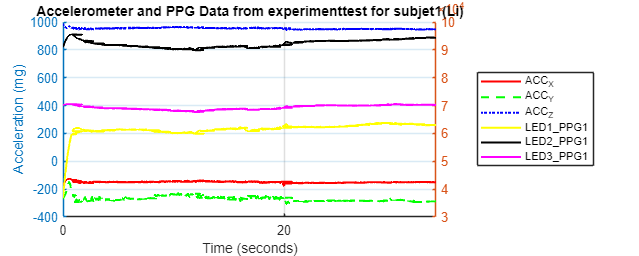

figure;
set(gcf, 'Position', [100, 100, 2000, 800]);  % [x, y, width, height]
yyaxis left;
hold on;
h1 = plot(data.Time_in_seconds, smoothed_acc_x, 'r', 'LineWidth', 1.5); 
h2 = plot(data.Time_in_seconds, smoothed_acc_y, 'g', 'LineWidth', 1.5); 
h3 = plot(data.Time_in_seconds, smoothed_acc_z, 'b', 'LineWidth', 1.5);
xlabel('Time (seconds)');
xlabel('Time (seconds)');
ylabel('Acceleration (mg)');
legend('ACC_X', 'ACC_Y', 'ACC_Z');
grid on;


yyaxis right;
h4 = plot(data.Time_in_seconds, smoothed_LED1, 'Color', 'yellow', 'LineWidth', 1.5, 'LineStyle', '-');  
h5 = plot(data.Time_in_seconds, smoothed_LED2, 'Color', 'black', 'LineWidth', 1.5, 'LineStyle', '-'); 
h6 = plot(data.Time_in_seconds, smoothed_LED3, 'Color', 'magenta', 'LineWidth', 1.5, 'LineStyle', '-'); 

% ylim([2e5 2.5e5]); 

legend([h1, h2, h3, h4, h5, h6], {'ACC_X', 'ACC_Y', 'ACC_Z', 'LED1\_PPG1', 'LED2\_PPG1', 'LED3\_PPG1'}, 'Location', 'eastoutside');
title(finalTitle);
hold off;
xticks(min(data.Time_in_seconds):20:max(data.Time_in_seconds));
xtickformat('%.0f');
xlim([0 max(data.Time_in_seconds)])

exportgraphics(gcf, exportPath+"\combined plot for acc and PPG data for experiment"+ experimentNumber +" of subject"+subject+".png", 'Resolution', 1000);